%Pole placement
% Define the system matrices A and B based on the given system
a = 5;
b = 3;
c = 1;
A = [a-b, 0.5-c; 0, 1];
B = [0; 1];

% Define the selected sampling interval(tau = h)
h = linspace(0, 20, 20);% Choice of sampling interval
E = zeros(length(h), length(h));
Tau = zeros(length(h), length(h));

x = sdpvar(4,4); % x = inv(P)
y = sdpvar(1,4); % y = K*inv(P), dim(K) = dim(y)

con1 =[];
con2 = [x >= eye(4,4)^(-10)];
for i =1:length(h)
        tau = 0:0.01:0.5*h(i);
        j = numel(tau);
%when 0=<tau<h
        %new augumented system to match dimension
        Fx = expm(A*h(i));
        Fu = (expm(A*h(i)) - expm(A*(h(i)-tau(j))))/A * B;
        G1 = (expm(A*(h(i)-tau(j))) - eye(size(A)))/A * B;
        Fe = [Fx, Fu, zeros(2,1); zeros(1,4); zeros(1,2), 1, 0];
        Ge = [G1; 1; 0];
% Check stability using LMIs(for discrete-time case)
con1 = [con1; [x, Fe*x-Ge*y; x*(Fe)'-(Ge*y)', x] >= eye(8,8)^(-10)];
cons = [con1, con2];
options = sdpsettings('solver', 'sedumi');
sol = optimize(cons, [], options);
F_cl1 = F - G * K;
        e = max(abs(eig(F_cl1)));
        E(i, j) = e;
        Tau(i,j) = tau(j);
end

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 14, order n = 13, dim = 81, blocks = 3
nnz(A) = 46 + 0, nnz(ADA) = 196, nnz(L) = 105
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.12E+00 0.000
  1 :   0.00E+00 6.20E-01 0.000 0.1989 0.9000 0.9000  -1.84  1  1  5.1E+00
  2 :   0.00E+00 3.33E-02 0.000 0.0537 0.9900 0.9900  -0.79  1  1  3.2E+00
  3 :   0.00E+00 3.07E-04 0.000 0.0092 0.9990 0.9990  -1.00  1  1  3.3E+00
  4 :   0.00E+00 2.82E-06 0.000 0.0092 0.9990 0.9990  -1.00  1  1  3.3E+00
  5 :   0.00E+00 2.61E-08 0.000 0.0093 0.9990 0.9990  -1.00  1  1  3.3E+00
  6 :   0.00E+00 2.40E-10 0.000 0.0092 0.9990 0.9990  -1.00  1  3  3.3E+00

Dual infeasible, primal improving direction found.
iter seconds  |Ax|    [Ay]_+     |x|       |y|
  6      0.1   2.0e-10   3.8e-16   7.1e-01   3.3e+00

Detailed timing (sec)
   Pre          IPM          Post
1.424E-02    2.940E-02    1.95

The coefficient matrix is not full row rank, numerical problems may occur.
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 14, order n = 117, dim = 913, blocks = 16
nnz(A) = 774 + 0, nnz(ADA) = 196, nnz(L) = 105
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.59E+01 0.000
  1 :   0.00E+00 1.19E+01 0.000 0.7494 0.9000 0.9000  -4.80  1  1  4.3E+02
Run into numerical problems.

iter seconds  |Ax|    [Ay]_+     |x|       |y|
  1      0.0   4.0e+01   3.9e-05   7.6e+00   9.7e-10
Failed: no sensible solution/direction found.

Detailed timing (sec)
   Pre          IPM          Post
5.756E-02    2.327E-02    2.615E-03    
Max-norms: ||b||=0, ||c|| = 1,
Cholesky |add|=0, |skip| = 2, ||L.L|| = 1.10584.


The coefficient matrix is not full row rank, numerical problems may occur.
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 14, order n = 125, dim = 977, blocks = 17
nnz(A) = 830 + 0, nnz(ADA) = 196, nnz(L) = 105
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.69E+01 0.000
  1 :   0.00E+00 1.26E+01 0.000 0.7450 0.9000 0.9000  -4.81  1  1  4.6E+02
Run into numerical problems.

iter seconds  |Ax|    [Ay]_+     |x|       |y|
  1      0.0   4.3e+01   6.7e-07   7.8e+00   2.7e-13
Failed: no sensible solution/direction found.

Detailed timing (sec)
   Pre          IPM          Post
2.530E-02    1.794E-02    2.072E-03    
Max-norms: ||b||=0, ||c|| = 1,
Cholesky |add|=1, |skip| = 2, ||L.L|| = 1.


The coefficient matrix is not full row rank, numerical problems may occur.
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 14, order n = 133, dim = 1041, blocks = 18
nnz(A) = 886 + 0, nnz(ADA) = 196, nnz(L) = 105
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.79E+01 0.000
  1 :   0.00E+00 1.41E+01 0.000 0.7862 0.9000 0.9000  -4.82  1  8  2.2E+02
Run into numerical problems.

iter seconds  |Ax|    [Ay]_+     |x|       |y|
  1      0.0   5.0e+01   3.6e-05   8.6e+00   1.1e-10
Failed: no sensible solution/direction found.

Detailed timing (sec)
   Pre          IPM          Post
2.875E-02    4.310E-02    2.545E-03    
Max-norms: ||b||=0, ||c|| = 1,
Cholesky |add|=1, |skip| = 5, ||L.L|| = 1.


The coefficient matrix is not full row rank, numerical problems may occur.
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 14, order n = 141, dim = 1105, blocks = 19
nnz(A) = 942 + 0, nnz(ADA) = 196, nnz(L) = 105
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.89E+01 0.000
  1 :   0.00E+00 1.41E+01 0.000 0.7480 0.9000 0.9000  -4.83  1  1  5.2E+02
Run into numerical problems.

iter seconds  |Ax|    [Ay]_+     |x|       |y|
  1      0.0   4.8e+01   6.5e-08   8.3e+00   2.1e-15
Failed: no sensible solution/direction found.

Detailed timing (sec)
   Pre          IPM          Post
2.591E-02    2.839E-02    2.002E-03    
Max-norms: ||b||=0, ||c|| = 1,
Cholesky |add|=1, |skip| = 5, ||L.L|| = 1.


The coefficient matrix is not full row rank, numerical problems may occur.
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 14, order n = 149, dim = 1169, blocks = 20
nnz(A) = 998 + 0, nnz(ADA) = 196, nnz(L) = 105
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.99E+01 0.000
  1 :   0.00E+00 1.47E+01 0.000 0.7377 0.9000 0.9000  -4.84  1  1  5.4E+02
Run into numerical problems.

iter seconds  |Ax|    [Ay]_+     |x|       |y|
  1      0.0   5.0e+01   2.3e-08   8.6e+00   2.6e-16
Failed: no sensible solution/direction found.

Detailed timing (sec)
   Pre          IPM          Post
3.627E-02    3.860E-02    1.881E-03    
Max-norms: ||b||=0, ||c|| = 1,
Cholesky |add|=1, |skip| = 5, ||L.L|| = 1.


The coefficient matrix is not full row rank, numerical problems may occur.
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 14, order n = 157, dim = 1233, blocks = 21
nnz(A) = 1054 + 0, nnz(ADA) = 196, nnz(L) = 105
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.09E+01 0.000
Run into numerical problems.

iter seconds  |Ax|    [Ay]_+     |x|       |y|
  0      0.0   7.8e+01   0.0e+00   1.2e+01   0.0e+00
Failed: no sensible solution/direction found.

Detailed timing (sec)
   Pre          IPM          Post
3.821E-02    2.109E-02    4.828E-03    
Max-norms: ||b||=0, ||c|| = 1,
Cholesky |add|=0, |skip| = 5, ||L.L|| = 1.


The coefficient matrix is not full row rank, numerical problems may occur.
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 14, order n = 165, dim = 1297, blocks = 22
nnz(A) = 1110 + 0, nnz(ADA) = 196, nnz(L) = 105
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.19E+01 0.000
Run into numerical problems.

iter seconds  |Ax|    [Ay]_+     |x|       |y|
  0      0.0   8.2e+01   0.0e+00   1.3e+01   0.0e+00
Failed: no sensible solution/direction found.

Detailed timing (sec)
   Pre          IPM          Post
2.505E-02    1.475E-02    1.740E-03    
Max-norms: ||b||=0, ||c|| = 1,
Cholesky |add|=0, |skip| = 5, ||L.L|| = 1.


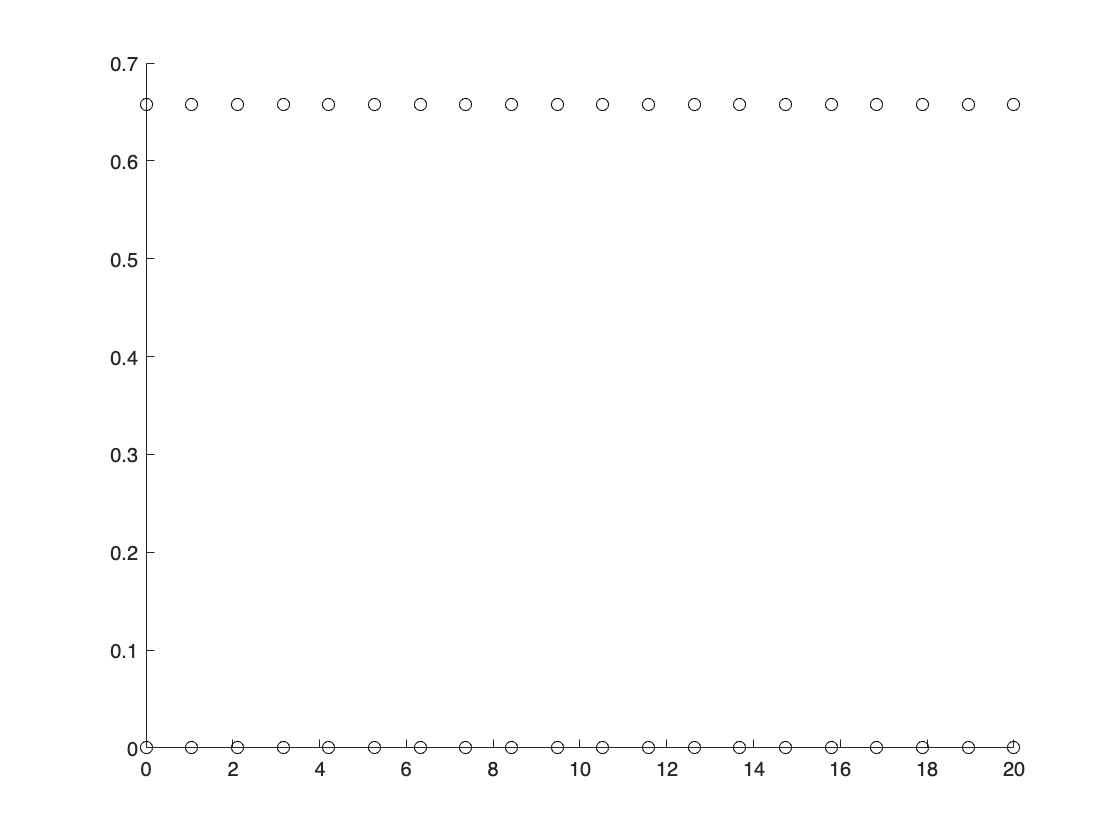

scatter(h,E,'k');


disp(sol.info);

Numerical problems (SeDuMi-1.3)



% if sol.problem == 0
%     disp('The sampled-data controller is stable.');
%     X = value(x)
%     Y = value(y)
%     K = Y * inv(X)
% else
%     disp('The sampled-data controller is unstable.');
% end
%Ke1 = Fe - Ge*K;
%eig(Ke1); %stable

% % Plot
% result = zeros(size(h));
% for i = 1:length(h)
%     hk = 0.5*h(i);            % Inter-sample time for (0.5*h)^\omega
%     tau = 0.5 * hk(i);        % Time-varying delays
%     % When 0 <= tau < h
%         Fx = expm(A*h(i));
%         Fu = (expm(A*h(i)) - expm(A*(h(i)-tau)))/A * B;
%         G1 = (expm(A*(h(i)-tau)) - eye(size(A)))/A * B;
%         Fe = [Fx, Fu, zeros(2,1); zeros(1,4); zeros(1,2), 1, 0];
%         Ge = [G1; 1; 0];
% 
%     Ke1 = Fe - Ge*K;
%     result(i) = max(abs(eig(Ke1))) ;
%     %result(i) = max(abs(eig(Ke1))) < 1; %it should be all '1'
% end
% 
% % Plotting
% plot(tau, result, 'o-');
% xlabel('tau');
% ylabel('abs(Ke1)');
% title('Stability Region for Different tau');
% 